% Load and show image
I = imread("Lenna.jpg")

I = 512×512×3 uint8 array
I(:,:,1) =

   226   226   223   223   226   226   228   227   227   225   228   225   223   226   223   221   221   221   222   222   223   223   224   221   218   221   223   225   221   221   220   223   225   223   226   223   225   227   229   231   231   232   230   233   234   237   233   231   237   238   234   235   234   232   233   230   227   221   219   213   203   202   187   174   169   166   158   153   155   157   166   161   166   165   169   170   174   174   175   180   177   178   177   177   175   175   173   179   177   178   177   178   182   178   178   179   176   179   178   174   173   174   179   180   177   182   182   185   187   190   194   194   190   199   195   193   195   196   192   201   203   202   206   197   201   205   202   206   205   207   209   203   204   205   202   204   200   206   204   206   207   204   203   206   205   207   203   201   202   203   204   202   205   201   204   202   205   207   206   206  

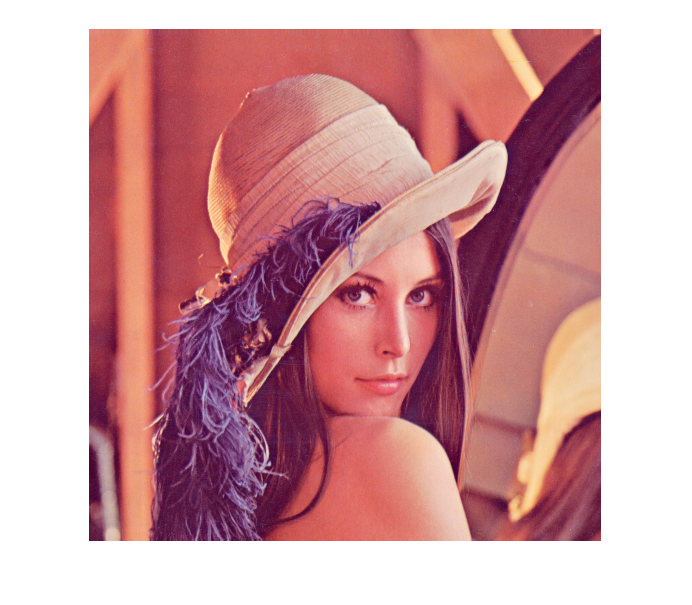

imshow(I)

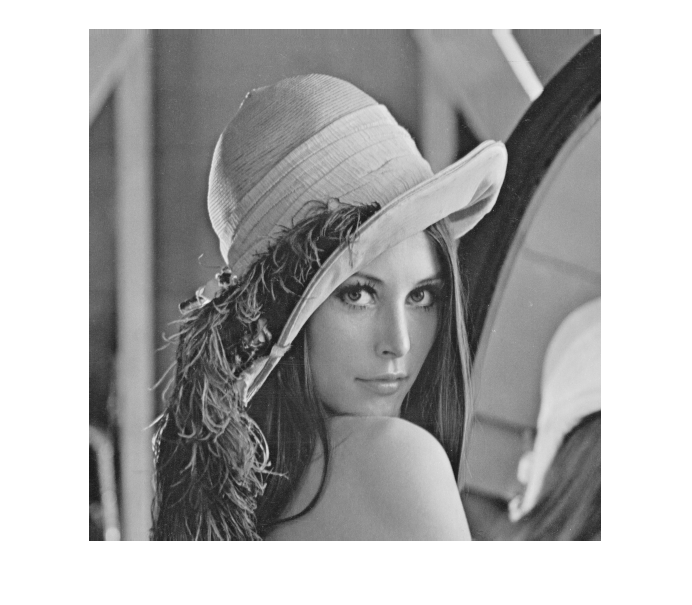


% Convert image to grayscale
I = rgb2gray(I);
figure
imshow(I)

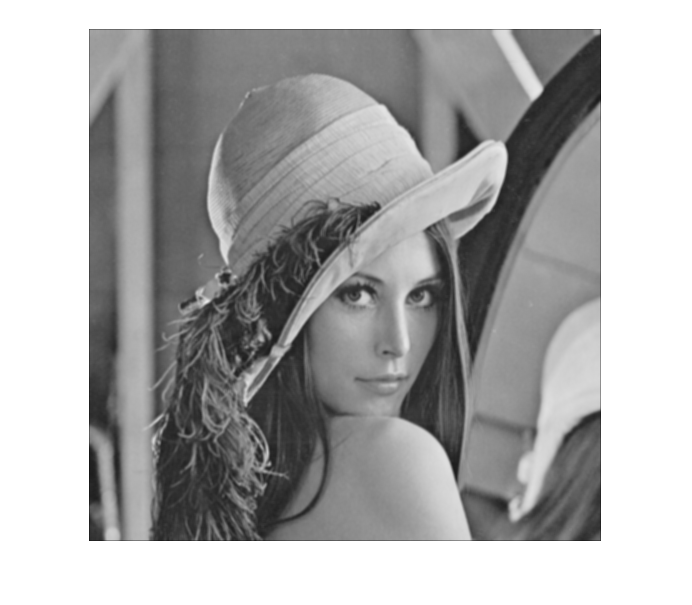


% Use 3X3 kernel with sigma=2 
kernel = fspecial('gaussian', [3 3], 2);
a = imfilter(I, kernel);
imshow(a)

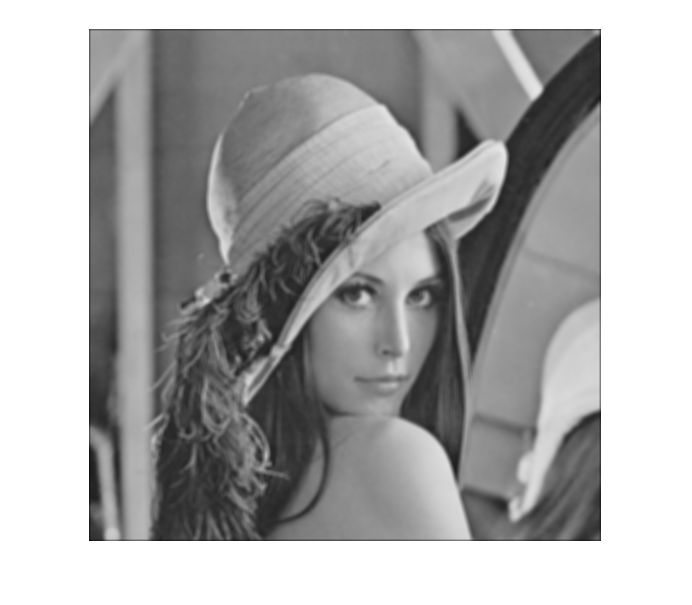

imwrite(a, '3x3kernel.jpg');

% Use 5X5 kernel with sigma=4 
kernel = fspecial('gaussian', [5 5], 4);
b = imfilter(I, kernel);
imshow(b)

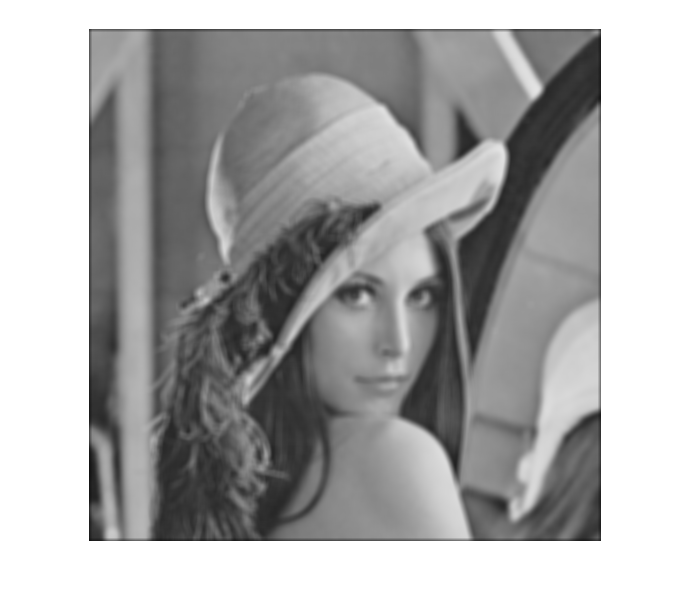

imwrite(b, '5x5kernel.jpg');

% Use 7X7 kernel with sigma=8 
kernel = fspecial('gaussian', [7 7], 8);
c = imfilter(I, kernel);
imshow(c)

imwrite(c, '7x7kernel.jpg');
